% Parameters
opts.dt   = 1e-4;
opts.nDFT = 256;
opts.D    = 0.228;
opts.U    = 229;
absx      = 1; 
nb        = 22; 
rho0      = 1.226;
opts.c0   = 340.156; 
c0        = opts.c0;
nSt       = 52; % Number of saved lighthill frequencies
nx        = 576; 
nr        = 81;
nt        = 128;
nt1       = nt + 1;

% Get Strouhals
Sts = dft_parameters(opts);
Sts = Sts(1:nSt);

% Load coordinates
load('~/JER_round/JER_round/SPOD/xrcoord.mat'); xs = x(:,1); rs = r(1,:);

% Polar angles in degrees
chi1 = 20; chi2 = 160; dchi = 5;
chis = chi1:dchi:chi2;
n = length(chis);

## **Intensity calculation over multiple polar angles for one (m,St) lighthill mode, averaged over blocks**

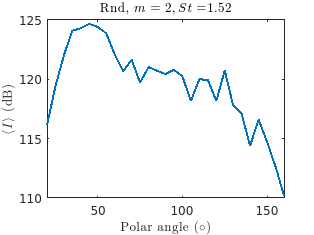

% Choose m,Stidx and md
m = 2;
Stidx = 40; % Has to be between 1 and 52 - saved 52. 
md = 'r';
usewinx = 0;

% Loop over blocks
Imf = zeros([n,1]); 
for bidx = 1:nb
    Z = loadlhmode(m,Stidx,bidx,md);
    [pmfb,~,~] = far_field_pressure_calc_v2(Z,m,Stidx,md, ...
                                            absx,chis,rs,xs, ...
                                            usewinx,opts); % Calculate pressure 
    Imfb = ((abs(pmfb)).^2)/(rho0*c0);  % Calculate intensity
    Imf = Imf + Imfb; 
end
Imf = Imf/nb; % Take mean over blocks
I0 = 1e-12; Imfdb = 10*log10(Imf/I0);

% Plot 
St = Sts(Stidx);
if strcmp(md,'r')
    jetlabel = 'Rnd';
elseif strcmp(md,'c')
    jetlabel = 'Chv';
end

fig = figure;
plot(chis,Imfdb,'LineWidth',1.5)
xlim([chi1,chi2])
xlabel('Polar angle ($\circ$)','Interpreter','latex')
ylabel('$\langle I \rangle$ (dB)','Interpreter','latex')
title([jetlabel ', $m = ' num2str(m) ',St = $' num2str(round(St,2))],'Interpreter','latex')

## **Intensity calculation over multiple polar angles for one (m,St) lighthill mode, showing individual blocks.**

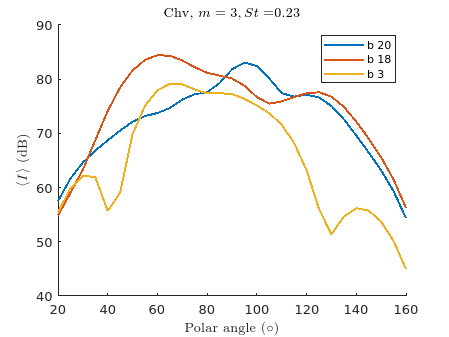

% Choose m,Stidx,md and number of blocks to plot
m = 3;
Stidx = 7; % Has to be between 1 and 52 - saved 52. 
md = 'c';
nblk = 3;
usewinx = 0;

% Randomly generate nblk integers between 1 and 22
bls = randsample(22,nblk);

% Loop over blocks
fig = figure;
if strcmp(md,'r')
    jetlabel = 'Rnd';
elseif strcmp(md,'c')
    jetlabel = 'Chv';
end
St = Sts(Stidx);
hold on
for i = 1:nblk
    bidx = bls(i);
    Z = loadlhmode(m,Stidx,bidx,md);
    [pmfb,~,~] = far_field_pressure_calc_v2(Z,m,Stidx,md, ...
                                            absx,chis,rs,xs, ...
                                            usewinx,opts); % Calculate pressure 
    Imfb = ((abs(pmfb)).^2)/(rho0*c0);  % Calculate intensity
    I0 = 1e-12; Imfbdb = 10*log10(Imfb/I0);
    plot(chis,Imfbdb,'LineWidth',1.5,'DisplayName',['b ' num2str(bidx)])
end
hold off
xlabel('Polar angle ($\circ$)','Interpreter','latex')
ylabel('$\langle I \rangle$ (dB)','Interpreter','latex')
title([jetlabel ', $m = ' num2str(m) ',St = $' num2str(round(St,2))],'Interpreter','latex')
legend()

## **Intensity calculation over multiple polar angles combining all m for one St, averaged over blocks**

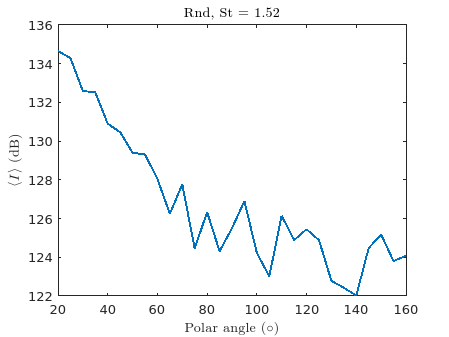

% Choose Strouhal index, jet and azimuthal mode to sum up to 
Stidx = 40;
md = 'r';
mup = 7;
usewinx = 0;

% Loop over blocks
If = zeros([n,1]);
for bidx = 1:nb
    pfb = zeros([n,1]);
    for m = 0:mup

        Z = loadlhmode(m,Stidx,bidx,md);
        [pmfb,~,~] = far_field_pressure_calc_v2(Z,m,Stidx,md, ...
                                            absx,chis,rs,xs, ...
                                            usewinx,opts);
        pfb = pfb + pmfb; % Add the azimuthal terms in the sum together

    end
    Ifb = ((abs(pfb)).^2)./(rho0*c0);
    If = If + Ifb;
end
If = If/nb; % Take mean over blocks
I0 = 1e-12; Ifdb = 10*log10(If/I0);

% Plot 
St = Sts(Stidx);
if strcmp(md,'r')
    jetlabel = 'Rnd';
elseif strcmp(md,'c')
    jetlabel = 'Chv';
end

fig = figure;
plot(chis,Ifdb,'LineWidth',1.5)
xlabel('Polar angle ($\circ$)','Interpreter','latex')
ylabel('$\langle I \rangle$ (dB)','Interpreter','latex')
title([jetlabel ', St = $' num2str(round(St,2)) '$'],'Interpreter','latex')

## **Intensity calculation for one polar angle and one m for different St, averaged over blocks**

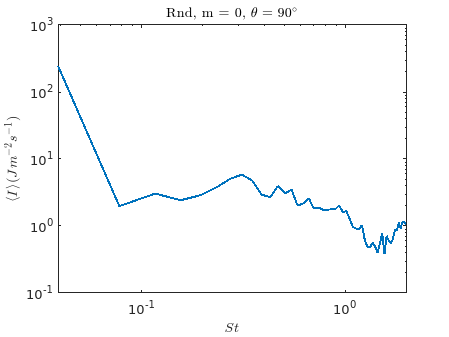

% Choose m,polar angle and jet
m = 0;
chi = 90; % In degrees
md = 'r';
usewinx = 0;

% Loop over blocks
Imfc = zeros([1,nSt]);
for bidx = 1:nb 
    for Stidx = 1:nSt
        Z = loadlhmode(m,Stidx,bidx,md);
        [pmfb,~,~] = far_field_pressure_calc_mfbx(Z,m,Stidx,md, ...
                                            absx,chi,rs,xs, ...
                                            usewinx,opts);
        Imfbc = ((abs(pmfb).^2))/(rho0*c0);
        Imfc(Stidx) = Imfc(Stidx) + Imfbc;
    end
end
Imfc = Imfc/nb; % Average over blocks

% Plot
fig = figure;
if strcmp(md,'r')
    jetlabel = 'Rnd';
elseif strcmp(md,'c')
    jetlabel = 'Chv';
end
loglog(Sts,Imfc,'LineWidth',1.5)
xlabel('$St$','Interpreter','latex')
ylabel('$\langle I \rangle (Jm^{-2}s^{-1})$','Interpreter','latex')
title([jetlabel ', m = ' num2str(m) ', $\theta = ' num2str(chi) '^\circ$'],'Interpreter','latex')

## **Intensity calculation for one polar angle combining all m for different St, averaged over blocks**

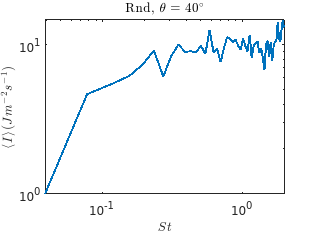

% Choose upper m to sum to, polar angle and jet
mup = 7;
chi = 40; % In degrees
md = 'r';
usewinx = 0;

% Loop over blocks
Imfc = zeros([1,nSt]);
for bidx = 1:nb 
    for Stidx = 1:nSt
        for m = 0:mup
            Z = loadlhmode(m,Stidx,bidx,md);
            [pmfb,~,~] = far_field_pressure_calc_mfbx(Z,m,Stidx,md, ...
                                                absx,chi,rs,xs, ...
                                                usewinx,opts);
            Imfbc = ((abs(pmfb).^2))/(rho0*c0);
            Imfc(Stidx) = Imfc(Stidx) + Imfbc;
        end
    end
end
Imfc = Imfc/nb; % Average over blocks

% Plot
fig = figure;
if strcmp(md,'r')
    jetlabel = 'Rnd';
elseif strcmp(md,'c')
    jetlabel = 'Chv';
end
loglog(Sts,Imfc,'LineWidth',1.5)
xlabel('$St$','Interpreter','latex')
ylabel('$\langle I \rangle (Jm^{-2}s^{-1})$','Interpreter','latex')
title([jetlabel ', $\theta = ' num2str(chi) '^\circ$'],'Interpreter','latex')

## **Intensity calculation integrated over frequency combined over all m for different polar angles (OASPL)**

oaspl = zeros([1,n]);
dSt = Sts(2)-Sts(1);
mup = 7;
md = 'c';
usewinx = 0;
% domega = 2*pi*dSt*opts.U/opts.D;
for i = 1:n
    chi = chis(i)
    for bidx = 1:nb
        for Stidx = 1:nSt
            sumpmfb = 0;
            for m = 0:mup
                Z = loadlhmode(m,Stidx,bidx,md);
                [pmfb,~,~] = far_field_pressure_calc_mfbx(Z,m,Stidx,md, ...
                                                absx,chi,rs,xs, ...
                                                usewinx,opts);
                sumpmfb = sumpmfb + pmfb;
            end
            Imfbc = ((abs(sumpmfb).^2))/(rho0*c0);
            oaspl(i) = oaspl(i) + Imfbc;
        end
    end
end

chi = 20

chi = 25

chi = 30

chi = 35

chi = 40

chi = 45

chi = 50

chi = 55

chi = 60

chi = 65

chi = 70

chi = 75

chi = 80

chi = 85

chi = 90

chi = 95

chi = 100

chi = 105

chi = 110

chi = 115

chi = 120

chi = 125

chi = 130

chi = 135

chi = 140

chi = 145

chi = 150

chi = 155

chi = 160


oaspl = oaspl/nb;

oaspldb = 10*log10(oaspl*1e12);

% Plot
fig = figure;
plot(chis,oaspldb,'LineWidth',1.5)

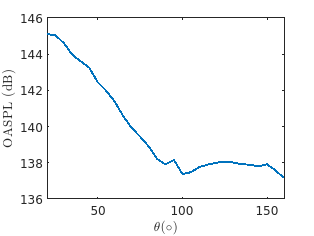

xlabel('$\theta (\circ)$','Interpreter','latex')
xlim([chi1,chi2])
ylabel('OASPL (dB)','Interpreter','latex')
exportgraphics(fig,'test.jpg','Resolution',300)

save('oaspl_chv.mat','oaspl')

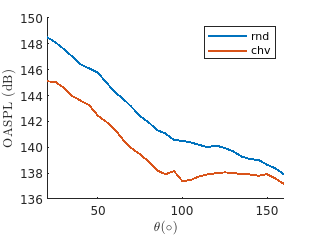

% Plot rnd and chv together
load oaspl_rnd.mat
oasplrnd = oaspl; clear oaspl;
oasplrnddb = 10*log10(oasplrnd*1e12);
load oaspl_chv.mat
oasplchv = oaspl; clear oaspl;
oasplchvdb = 10*log10(oasplchv*1e12);

% Plot
fig = figure;
hold on
plot(chis,oasplrnddb,'LineWidth',1.5,'DisplayName','rnd')
plot(chis,oasplchvdb,'LineWidth',1.5,'DisplayName','chv')
hold off
xlabel('$\theta (\circ)$','Interpreter','latex')
xlim([chi1,chi2])
ylabel('OASPL (dB)','Interpreter','latex')
legend()
exportgraphics(fig,'test.jpg','Resolution',300)

## **Intensity calculation for one m integrated over polar angle for different frequencies**

## **Intensity calculation integrated over polar angle combined over all m for different frequencies**

## Comparison of i**ntensity calculation over multiple polar angles for one (m,St) lighthill mode, averaged over blocks**

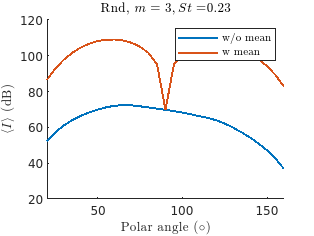

% Choose m,Stidx and md
m = 3;
Stidx = 7; % Has to be between 1 and 52 - saved 52. 
md = 'r';
usewinx = 1;

% Load mean velocities
if strcmp(md,'r')
    load ~/JER_round/JER_round/new_mesh/meanflows_tp.mat;
elseif strcmp(md,'c')
    load ~/JER_chev/JER_chev/meanflows_tp.mat;
end
flows = squeeze(flows([2,3],1,:)); 
Ubari = squeeze(flows(1,:)); 
Ubari = reshape(Ubari,[nx,nr,nt1]);
Ubarx = squeeze(mean(Ubari,3));
Ubari = squeeze(flows(2,:)); 
Ubari = reshape(Ubari,[nx,nr,nt1]);
Ubary = squeeze(mean(Ubari,3));
clear flows;

% Loop over blocks
Imf = zeros([n,1]); 
Imffbar = zeros([n,1]);
for bidx = 1:nb

    % Get fluctuating lighthill stresses
    Z = loadlhmode(m,Stidx,bidx,md);

    % Get mean flow addition
    udash = loadvmode(m,Stidx,bidx,md);
    udashx = squeeze(udash(:,:,1));
    udashy = squeeze(udash(:,:,2));
    clear udash
    Zbar = zeros([nx,nr,3]);
    Zbar(:,:,1) = 2*rho0*Ubarx.*udashx;
    Zbar(:,:,2) = 2*rho0*Ubarx.*udashy;
    Zbar(:,:,3) = 2*rho0*Ubary.*udashy;

    % Add mean flow addition
    Zfbar = Z + Zbar;
    
    [pmfb,~,~] = far_field_pressure_calc_v2(Z,m,Stidx,md, ...
                                            absx,chis,rs,xs, ...
                                            usewinx,opts); % Calculate pressure 
    [pmfbfbar,~,~] = far_field_pressure_calc_v2(Zfbar,m,Stidx,md, ...
                                            absx,chis,rs,xs, ...
                                            usewinx,opts); % Calculate pressure 
    Imfb = ((abs(pmfb)).^2)/(rho0*c0);  % Calculate intensity
    Imfbfbar = ((abs(pmfbfbar)).^2)/(rho0*c0);  % Calculate intensity
    Imf = Imf + Imfb;
    Imffbar = Imffbar + Imfbfbar;
end
Imf = Imf/nb; % Take mean over blocks
Imffbar = Imffbar/nb; % Take mean over blocks
I0 = 1e-12; Imfdb = 10*log10(Imf/I0); Imffbardb = 10*log10(Imffbar/I0);

% Plot 
St = Sts(Stidx);
if strcmp(md,'r')
    jetlabel = 'Rnd';
elseif strcmp(md,'c')
    jetlabel = 'Chv';
end

fig = figure;
hold on
plot(chis,Imfdb,'LineWidth',1.5,'DisplayName','w/o mean')
plot(chis,Imffbardb,'LineWidth',1.5,'DisplayName','w mean')
hold off
xlim([chi1,chi2])
xlabel('Polar angle ($\circ$)','Interpreter','latex')
ylabel('$\langle I \rangle$ (dB)','Interpreter','latex')
legend('Interpreter','latex')
title([jetlabel ', $m = ' num2str(m) ',St = $' num2str(round(St,2))],'Interpreter','latex')